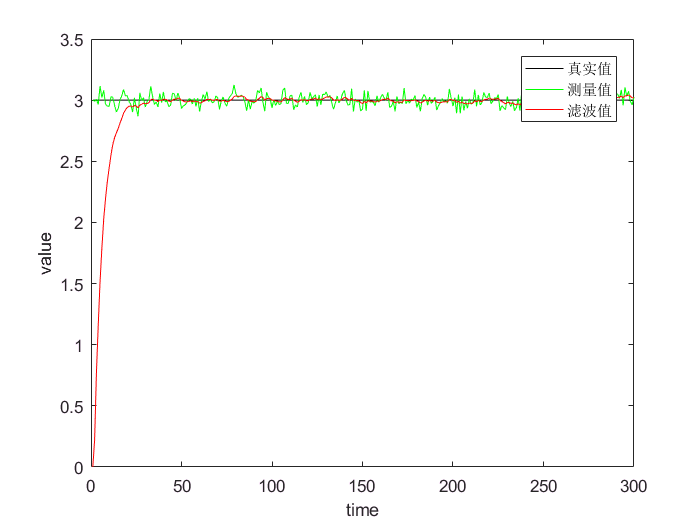

clc
% 初始化
Q=0.0001;  %过程噪声方差
R=0.0025;  %测量噪声方差
P0=0.0004; %测量协方差
 
% 系统模型建立
A=1;  % 状态转移矩阵
B=1;  
u=0;  % 输入
H=1;  % 测量矩阵
step=300;  %数据点个数
V=sqrt(R).*randn(1,step); % 测量噪声
 
% 开始仿真目标的状态和测量过程
X(1:step)=3.00; % 目标真实值的状态初始化
Z=zeros(1,step);Z(1,1)=X(1,1); % 测量值初始化
Xkf=zeros(1,step); % 卡尔曼滤波得到的状态初始化
P=zeros(1,step);P(1,1)=0.0001; % 协方差初始化
 
for k=2:step
    Z(1,k)=H*X(1,k)+V(1,k); % 观测方程
    %预测方程
    Xpre=A*Xkf(1,k-1)+B*u; % 状态的一步预测
    P_pre=A*P(1,k-1)*A'+Q; % 协方差预测
    %滤波方程
    K=P_pre*H'*inv(H*P_pre*H'+R); % 计算卡尔曼增益矩阵
    Xkf(1,k)=Xpre+K*(Z(1,k)-H*Xpre); % 状态更新
    P(1,k)=(1-K*H)*Ppre; % 协方差更新
end

figure(1);
hold on;
box on;
xlabel('time');ylabel('value');
plot(1:step,X(1,1:step),'k'); % 真实值
plot(1:step,Z(1,1:step),'g'); % 测量值
plot(1:step,Xkf(1,1:step),'r'); % 滤波值
legend('真实值','测量值','滤波值');